This script uses analytical theory to fit experimental SAXS data of Polyimide-PEG random copolymers.

Load experiment data.

clear;
close all
addpath('functions/')
data = load('exp-data/PEG40undoped.csv');  % SAXS data with q in A^(-1)
                                           % 30wt ~= 16mol%
FA=0.165;    % chemical composition
alpha = 143.8532;  %intensity scaling
rm = 32.05; % estimate end-to-end distance of a "chemical monomer" in unit of Angstrom

TV = [22,40:20:180];  % temperature in degree C
TK = TV+273.15;       % temperature in Kelvin
q = data(:,1);
s = data(:,2:end);

Define a small q cutoff and estimate peak intensity S(q~=0).

% if PEG wt% = 0.30
qmin0 = 0.03803;
qminf = 0.04094;

iqmin0 = find(q==qmin0);
iqminf = find(q==qminf);
smin = mean(s(iqmin0:iqminf,:));
sminstd = std(1./s(iqmin0:iqminf,:));

figure;hold

Current plot held


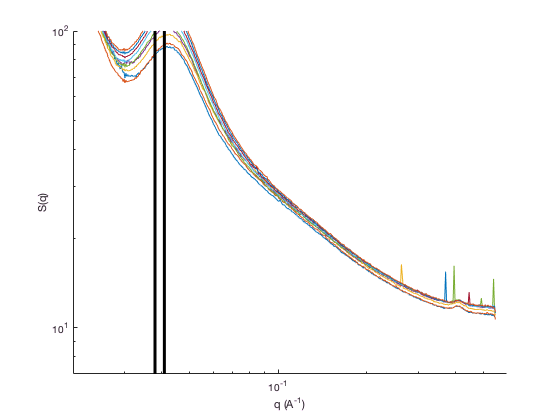

% at which temperature?
Trange=1:9;
for T=Trange
    plot(q,s(:,T));
end
plot([qmin0,qmin0],[7,1e2],'k-','linewidth',3)
plot([qminf,qminf],[7,1e2],'k-','linewidth',3)

xlabel('q (A^{-1})');ylabel('S(q)')
set(gca,'xscale','log');set(gca,'yscale','log');
xlim([0.02,0.6]);ylim([7,1e2]);